# Ejercicios raices

5.7 Determine the roots of f (x) = −12 − 21*x + 18*x^2 − 2.75*x^3 graphically. In addition, determine the first root of the function with bisection

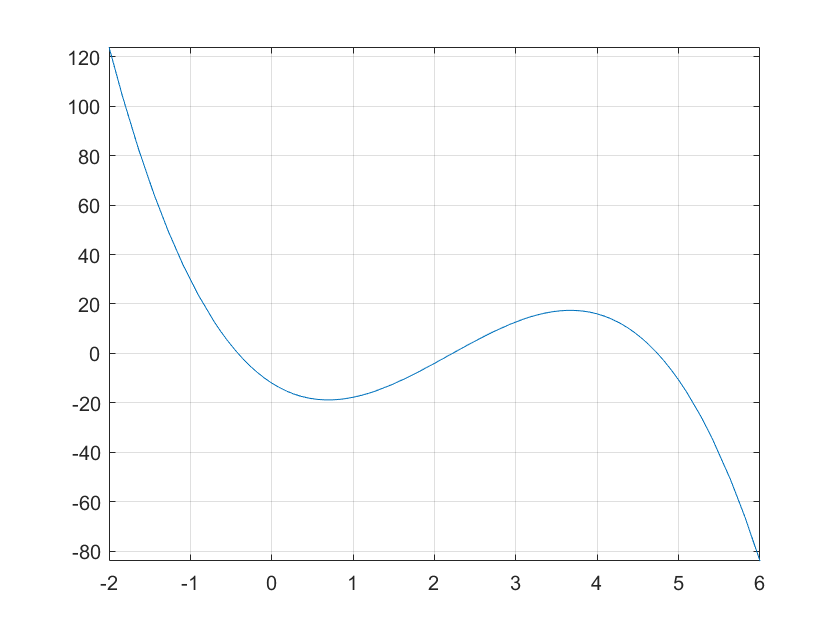

%
f=@(x) -12 -21*x +18*x.^2-2.75*x.^3;
fplot(f,[-2,6]);
grid on;

%Parece que los ceros están entre los valores de x: (-1,0), (2,3) y (4,5)


This plot indicates that roots are located at about –0.4, 2.25 and 4.7. La primera raíz está en [-1,0].

%
[x,iteraciones]=bisect(f,-2,6);
x

x = -0.4147

iteraciones

iteraciones = 57

%Se puede observar que por las derivadas de la función, es posible
%encontrar una raíz, pero para encontrar la raíz deseada es necesario
%elegir un valor de inicio que nos acerque a la raíz que estamos buscando.
%En este caso, al utilizar valores mayores a -9, al hacer las operaciones
%de la función y derivada, termina encontrando la 2da y 3er raíz.
[x,iteraciones]=newRap(f,-9);
x

x = -0.4147

iteraciones

iteraciones = 13

5.8 Locate the first nontrivial root of sin(x) = x^2 where x is in radians. Use a graphical technique and bisection.

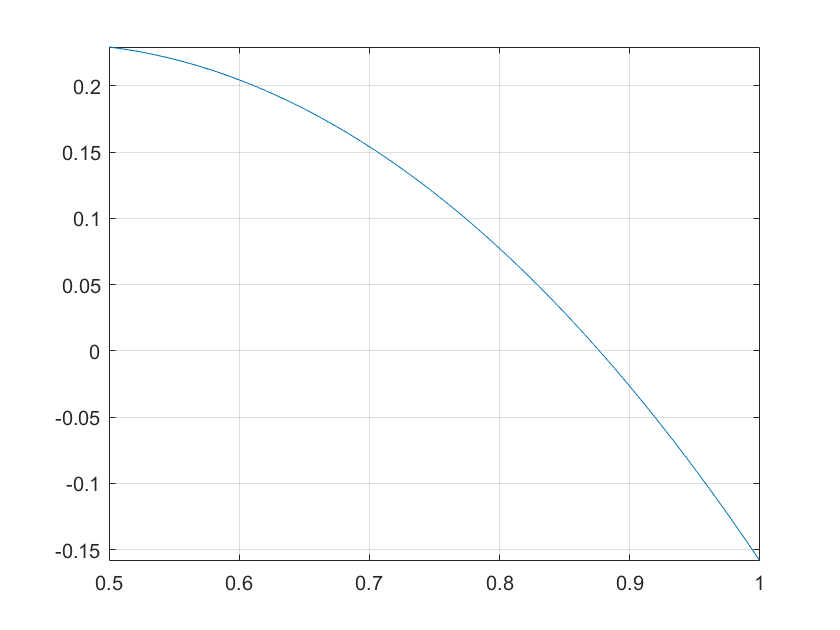

%La trivial es 0. La no trivial está entre 0.5 y 1
f=@(x) sin(x)-x.^2;
fplot(f,[0.5,1]);
grid on;

[x,iteraciones]=bisect(f,0.5,1);
x

x = 0.8767

iteraciones

iteraciones = 52

%En este caso, al utilizar valores mayores a -10, al hacer las operaciones
%de la función y derivada, termina encontrando la raíz no trivial, pero en
%otro caso encontramos la raíz x=0.
[x,iteraciones]=newRap(f,0);
x

x = 0.8767

iteraciones

iteraciones = 9

5.9 Determine the positive real root of ln(x^2) = 0.7 (a) graphically, (b) using the bisection method, with initial guesses of xl = 0.5 and xu = 2

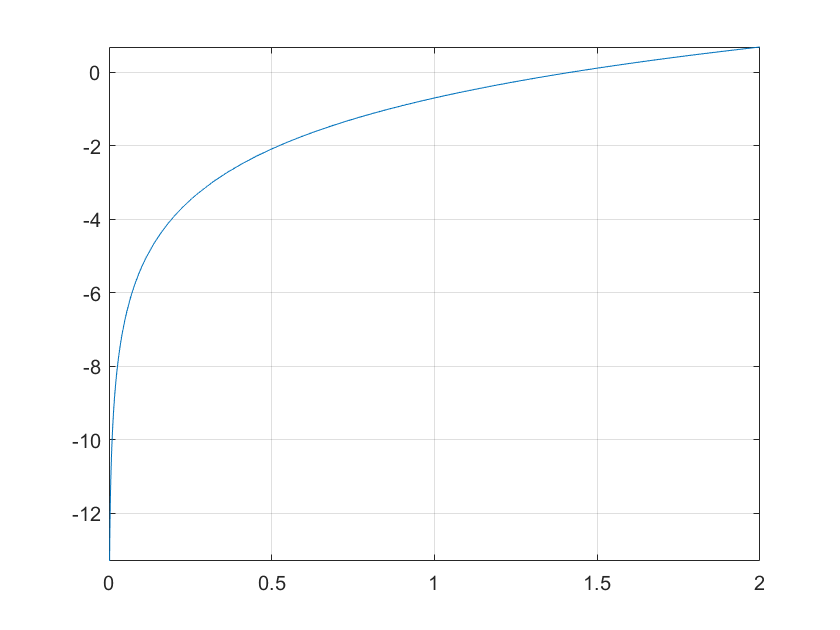

%La solución se encuentra entre 1 y 1.5
f=@(x) log(x.^2)-0.7;
fplot(f,[0,2]);
grid on;

[x,iteraciones]=bisect(f,1,1.5);
x

x = 1.4191

iteraciones

iteraciones = 51


%En este caso, al utilizar valores mayores a -10, 
%de la función y derivada, termina encontrando la única raíz. Pero si se
%elige algún valor mayor a 1, termina marcando x=Inf.
[x,iteraciones]=newRap(f,0);
x

x = Inf

iteraciones

iteraciones = 84

Escribe aquí la función bisección

function [x,i]=bisect(f,a,b)
    if f(a)*f(b)>0, error('f(a) y f(b) deben tener distinto signo'), end
    xizq=a;
    xder=b;
    x=(xizq+xder)/2;
    xprev=x*100;
    i=1;
    while abs((x-xprev)/x)>eps && f(x)~=0
        if f(x)*f(xizq)>0
            xizq=x;
        else
            xder=x;
        end
        i=i+1;
        xprev=x;
        x=(xizq+xder)/2;
    end
end

function [x,i]=newRap(f,xi)
    %xn+1=xn-f(xn)/f´(xn)
    xp=xi;
    x=xp+10;
    i=0;
    fsym=sym(f);
    dfs=diff(fsym);
    df=matlabFunction(dfs);
    if dfs==0, error('La derivada de la función es 0'), end
    while abs((x-xp)/x)>eps && f(x)~=0
        xp=x;
        x=xp-f(xp)/df(xp);
        i=i+1;
    end
end